sigma  = 2

sigma = 2


dx = 2

dx = 2

Ix = (@(x) (1/(sigma*(2*pi)^.5))*exp(-.5*(x+dx/2)^2/(sigma^2))+(1/(sigma*(2*pi)^.5))*exp(-.5*(x-dx/2)^2/(sigma^2)))

Ix = function_handle with value:
    @(x)(1/(sigma*(2*pi)^.5))*exp(-.5*(x+dx/2)^2/(sigma^2))+(1/(sigma*(2*pi)^.5))*exp(-.5*(x-dx/2)^2/(sigma^2))


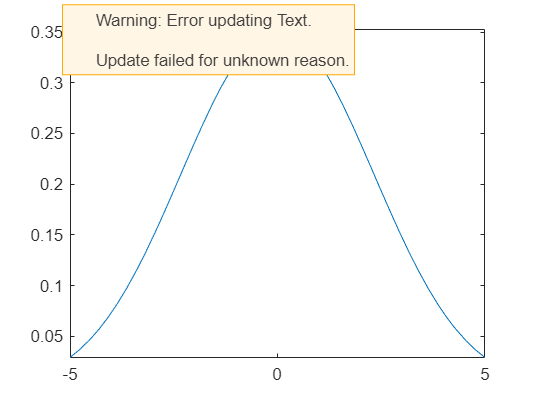


fplot(Ix)


dx = 4

dx = 4

Ix = (@(x) (1/(sigma*(2*pi)^.5))*exp(-.5*(x+dx/2)^2/(sigma^2))+(1/(sigma*(2*pi)^.5))*exp(-.5*(x-dx/2)^2/(sigma^2)))

Ix = function_handle with value:
    @(x)(1/(sigma*(2*pi)^.5))*exp(-.5*(x+dx/2)^2/(sigma^2))+(1/(sigma*(2*pi)^.5))*exp(-.5*(x-dx/2)^2/(sigma^2))


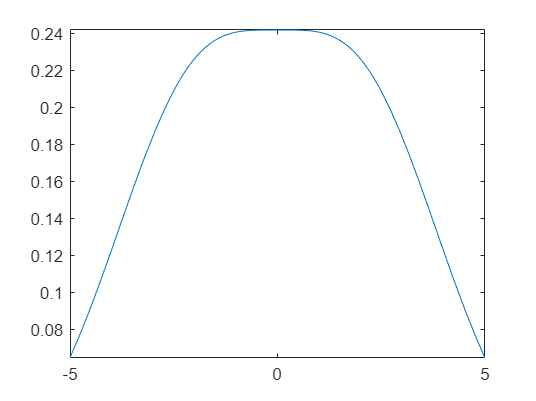


fplot(Ix)


dx = 6

dx = 6

Ix = (@(x) (1/(sigma*(2*pi)^.5))*exp(-.5*(x+dx/2)^2/(sigma^2))+(1/(sigma*(2*pi)^.5))*exp(-.5*(x-dx/2)^2/(sigma^2)))

Ix = function_handle with value:
    @(x)(1/(sigma*(2*pi)^.5))*exp(-.5*(x+dx/2)^2/(sigma^2))+(1/(sigma*(2*pi)^.5))*exp(-.5*(x-dx/2)^2/(sigma^2))


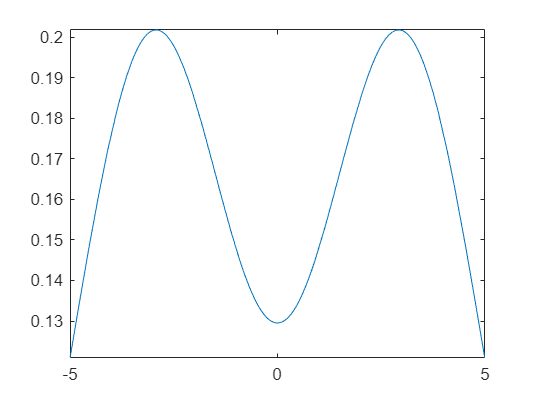


fplot(Ix)

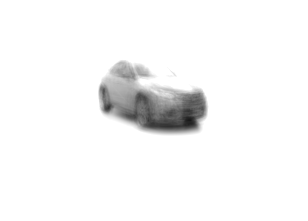

 

% car: 80 normalized 128 * 128 car images
  
  % Output:
  % meanA: the average car image reshaped to 1*16384
  % AAT: A*AT produced from training images
  % eigenvalues_top4: 4*1 array containing the largest 4 eigenvalues of AAT
  % rmse4: 4*1 array containing the rmse of the eigencar-based image approximation of the first 4 training images (cars with indices #1-4)

    mycars = zeros(128,128,80);
    for i = 1:80
        mycars(:,:,i) = cell2mat(cars(i));
    end 
    
    mycars_training = mycars(:,:,1:64);
    A = zeros([64 16384]);
    Atest = zeros([4 16384]);
    
    for j = 1:64
        tmp = reshape(mycars_training(:,:,j),1,[]);
        A(j,:) = tmp;
    end

    for j = 69:72
        tmp = reshape(mycars(:,:,j),1,[]);
        Atest(j-68,:) = tmp;
    end
    
    meanImg = mean(A);
    
    for j = 1:64
        A(j,:) = A(j,:) - meanImg;
    end

    for j = 1:4
        Atest(j,:) = Atest(j,:) - meanImg;
    end
    
    aat = A*A';    %aat = 64x64 
    [evectors, evalues] = eig(aat);
    evalues = max(evalues);
    
    [out, idxs] = sort(evalues, 'descend');
    
    evectors_perm = zeros([64 34]);
    for i = 1:34
        evectors_perm(:,i) = evectors(:,idxs(i));
    end
    
    %A' = 16___x64, evectors_perm = 64x34
    evectors_ata = A'*evectors_perm;
    
    unit_multiple = (sum(evectors_ata.^2)).^(.5);
    eigencars = zeros(size(evectors_ata));

    for i = 1:34
        %eigencars = 16___x34
        eigencars(:,i) = evectors_ata(:,i)/unit_multiple(i);
    end
    
    eigencar_images = zeros([128 128 34]);
    %34x16___
    eigencars = eigencars';
    eigencar_image_b = zeros([128 128]);
    for i=1:34
        eigencar_images(:,:,i) = reshape(eigencars(i, :), 128, 128);
        eigencar_image_b(:,:) = eigencar_image_b(:,:)+eigencar_images(:,:,i);
        %meanImg = reshape(meanImg, 128, 128);
        %eigencar_images(:,:,i) = tmp + meanImg/255;
    end
    
    imshow(reshape(meanImg, 128, 128))

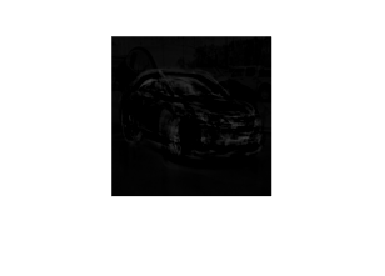

    eigencar_image_b;

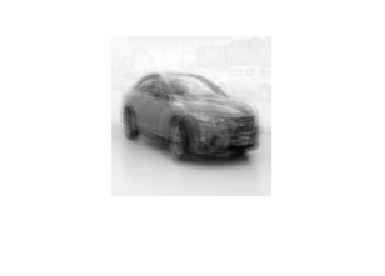

    eigencar_image_b = eigencar_image_b + reshape(meanImg, 128, 128);
    imshow(eigencar_image_b, []);

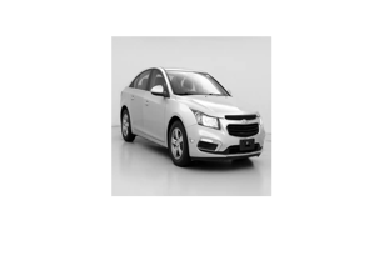


    
    
    testcar1 = reshape(mycars_training(:,:,1),[],1);
    %34x1 = 34x16___ * 16___x1
    coeffs1 = eigencars*(testcar1-meanImg');
    reconstructed1 = ((eigencars')*coeffs1)';
    imshow(mycars_training(:,:,1),[]);

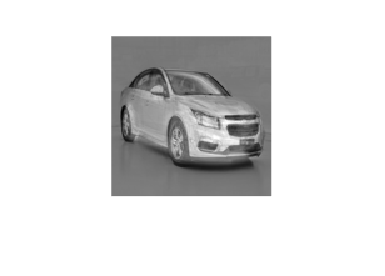

    imshow(reshape(reconstructed1,128,128),[]);

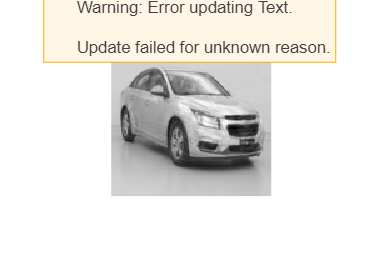

    imshow(reshape(meanImg + reconstructed1,128,128),[]);

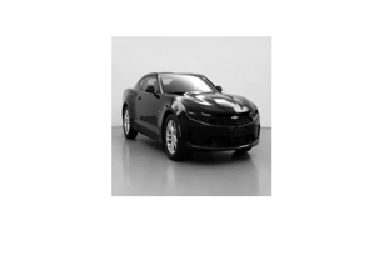


    
    testcar2 = reshape(mycars_training(:,:,2),[],1);
    coeffs2 = eigencars*(testcar2-meanImg');
    reconstructed2 = ((eigencars')*coeffs2)';
    imshow(mycars_training(:,:,2),[]);

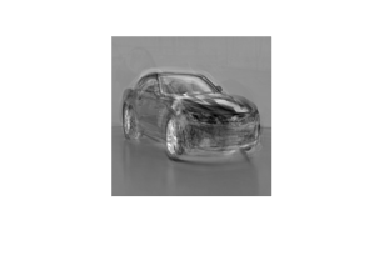

    imshow(reshape(reconstructed2,128,128),[]);

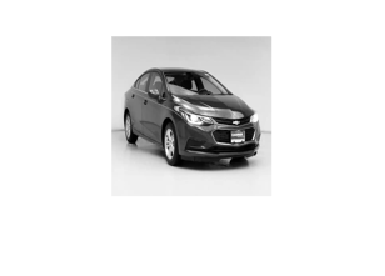

    
    testcar3 = reshape(mycars_training(:,:,3),[],1);
    coeffs3 = eigencars*(testcar3-meanImg');
    reconstructed3 = ((eigencars')*coeffs3)';
    imshow(mycars_training(:,:,3),[]);

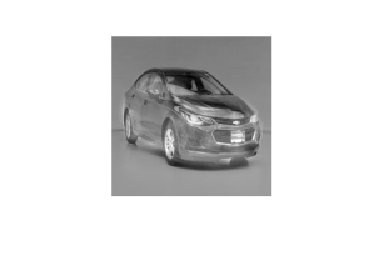

    imshow(reshape(reconstructed3,128,128),[]);

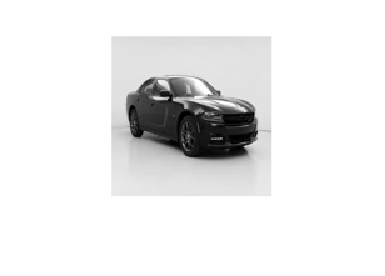

    
    testcar4 = reshape(mycars_training(:,:,4),[],1);
    testcar4mean = testcar4 - meanImg';
    coeffs4 = eigencars*(testcar4-meanImg');
    reconstructed4 = ((eigencars')*coeffs4)';

    imshow(mycars_training(:,:,4),[]);

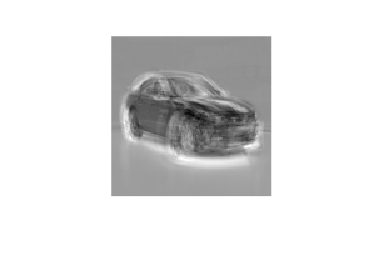

    imshow(reshape(reconstructed4,128,128),[]);

    
    meanA = meanImg;
    AAT = aat;
    eigenvalue_top4 = out(1:4)'

eigenvalue_top4 = 	1.0e+04 *

    1.9106
    1.5534
    0.6730
    0.3028


    
    rmse4 = [0; 0; 0; 0];
    
    rmse4(1) = error(reconstructed1, A(1,:));

error = 0.0608

    rmse4(2) = error(reconstructed2, A(2,:));

error = 0.0840

    rmse4(3) = error(reconstructed3, A(3,:));

error = 0.0436

    rmse4(4) = error(reconstructed4, A(4,:));

error = 0.0888

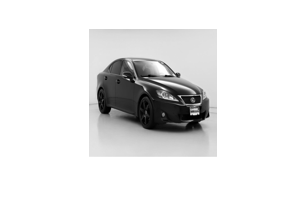



    testcar69 = reshape(mycars(:,:,69),[],1);
    %34x1 = 34x16___ * 16___x1
    coeffs69 = eigencars*(testcar69-meanImg');
    reconstructed69 = ((eigencars')*coeffs69)';
    imshow(mycars(:,:,69),[]);

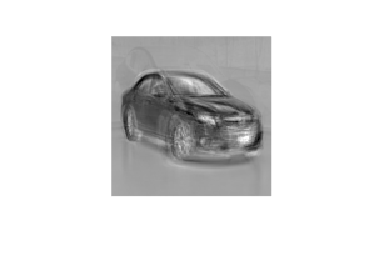

    imshow(reshape(reconstructed69,128,128),[]);

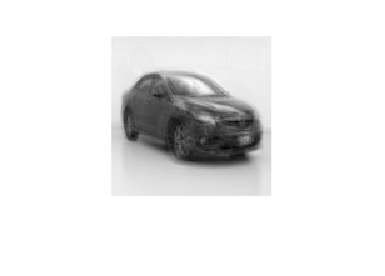

    imshow(reshape(meanImg + reconstructed69,128,128),[]);

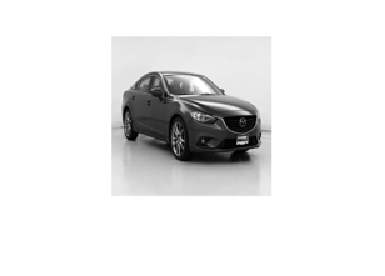


    
    testcar70 = reshape(mycars(:,:,70),[],1);
    %34x1 = 34x16___ * 16___x1
    coeffs70 = eigencars*(testcar70-meanImg');
    reconstructed70 = ((eigencars')*coeffs70)';
    imshow(mycars(:,:,70),[]);

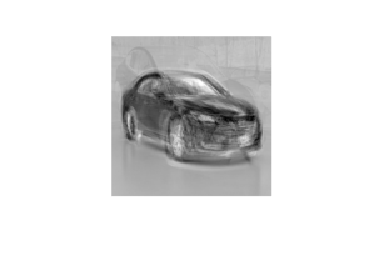

    imshow(reshape(reconstructed70,128,128),[]);

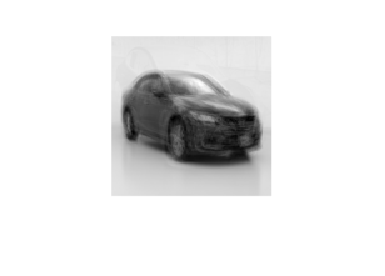

    imshow(reshape(meanImg + reconstructed70,128,128),[]);

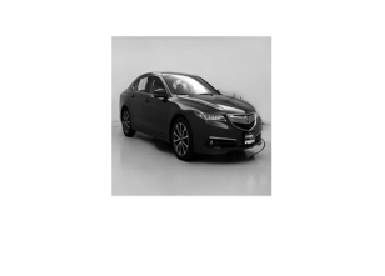


    testcar71 = reshape(mycars(:,:,71),[],1);
    %34x1 = 34x16___ * 16___x1
    coeffs71 = eigencars*(testcar71-meanImg');
    reconstructed71 = ((eigencars')*coeffs71)';
    imshow(mycars(:,:,71),[]);

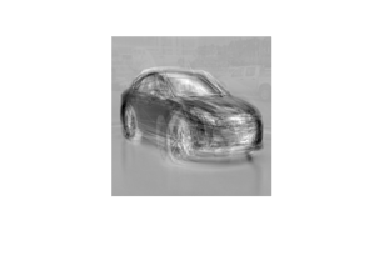

    imshow(reshape(reconstructed71,128,128),[]);

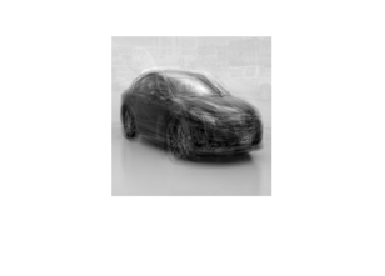

    imshow(reshape(meanImg + reconstructed71,128,128),[]);

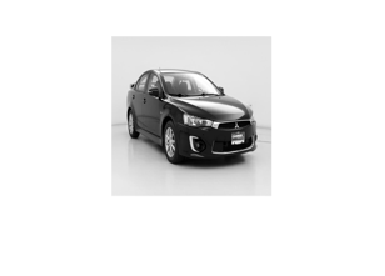


    testcar72 = reshape(mycars(:,:,72),[],1);
    %34x1 = 34x16___ * 16___x1
    coeffs72 = eigencars*(testcar72-meanImg');
    reconstructed72 = ((eigencars')*coeffs72)';
    imshow(mycars(:,:,72),[]);

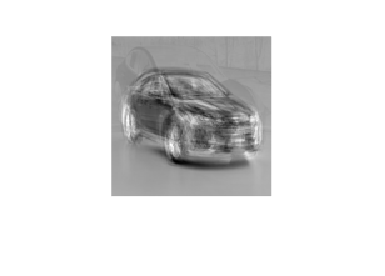

    imshow(reshape(reconstructed72,128,128),[]);

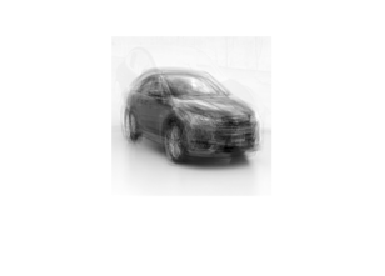

    imshow(reshape(meanImg + reconstructed72,128,128),[]);

    
    
    meanA = meanImg;
    AAT = aat;
    eigenvalue_top4 = out(1:4)'

eigenvalue_top4 = 	1.0e+04 *

    1.9106
    1.5534
    0.6730
    0.3028


    
    rmse4test = [0; 0; 0; 0];
    
    rmse4test(1) = error(reconstructed69, Atest(1,:));

error = 0.1424

    rmse4test(2) = error(reconstructed70, Atest(2,:));

error = 0.1106

    rmse4test(3) = error(reconstructed71, Atest(3,:));

error = 0.1316

    rmse4test(4) = error(reconstructed72, Atest(4,:));

error = 0.1688

    %DFT TIME


    

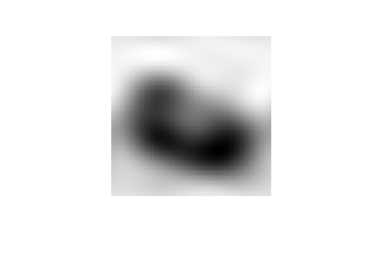



    
    [testcar1DFT, phase] = AmpPhaseDFT(mycars(:,:,65));
    testcar1DFT(:, 4:126) = zeros([65 123]);
    testcar1DFT(5:65, :) = zeros([61 128]);
    testcar1IDFT = ReconfromAmpPhase(testcar1DFT, phase);
    imshow(testcar1IDFT, [])

    err4(1) = error(testcar1IDFT, mycars(:,:,65))

error = 0.1843

err4 =     0.1843    0.1960    0.1777    0.1849


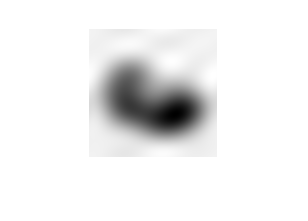

    
    [testcar2DFT, phase] = AmpPhaseDFT(mycars(:,:,73));
    testcar2DFT(:, 4:126) = zeros([65 123]);
    testcar2DFT(5:65, :) = zeros([61 128]);
    testcar2IDFT = ReconfromAmpPhase(testcar2DFT, phase);
    imshow(testcar2IDFT, [])

    err4(2) = error(testcar2IDFT, mycars(:,:,73))

error = 0.1960

err4 =     0.1843    0.1960    0.1777    0.1849


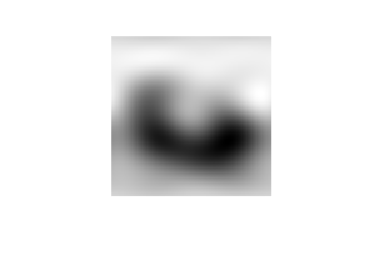

    
    [testcar3DFT, phase] = AmpPhaseDFT(mycars(:,:,79));
    testcar3DFT(:, 4:126) = zeros([65 123]);
    testcar3DFT(5:65, :) = zeros([61 128]);
    testcar3IDFT = ReconfromAmpPhase(testcar3DFT, phase);
    imshow(testcar3IDFT, [])

    err4(3) = error(testcar3IDFT, mycars(:,:,79))

error = 0.1777

err4 =     0.1843    0.1960    0.1777    0.1849


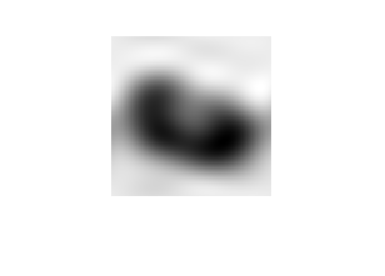

    
    [testcar4DFT, phase] = AmpPhaseDFT(mycars(:,:,70));
    testcar4DFT(:, 4:126) = zeros([65 123]);
    testcar4DFT(5:65, :) = zeros([61 128]);
    testcar4IDFT = ReconfromAmpPhase(testcar4DFT, phase);
    imshow(testcar4IDFT, [])

    err4(4) = error(testcar4IDFT, mycars(:,:,70))

error = 0.1849

err4 =     0.1843    0.1960    0.1777    0.1849


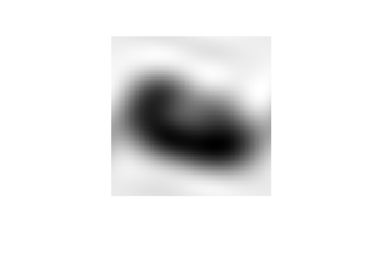


    errtest = err4;

    [testcar69DFT, phase] = AmpPhaseDFT(mycars(:,:,69));
    testcar69DFT(:, 4:126) = zeros([65 123]);
    testcar69DFT(5:65, :) = zeros([61 128]);
    testcar69IDFT = ReconfromAmpPhase(testcar69DFT, phase);
    imshow(testcar69IDFT, [])

    errtest(1) = error(testcar69IDFT, mycars(:,:,69))

error = 0.1986

errtest =     0.1986    0.1960    0.1777    0.1849


    
    [testcar70DFT, phase] = AmpPhaseDFT(mycars(:,:,70));
    testcar70DFT(:, 4:126) = zeros([65 123]);
    testcar70DFT(5:65, :) = zeros([61 128]);
    testcar70IDFT = ReconfromAmpPhase(testcar70DFT, phase);
    imshow(testcar70IDFT, [])

    errtest(2) = error(testcar70IDFT, mycars(:,:,70))

error = 0.1849

errtest =     0.1986    0.1849    0.1777    0.1849


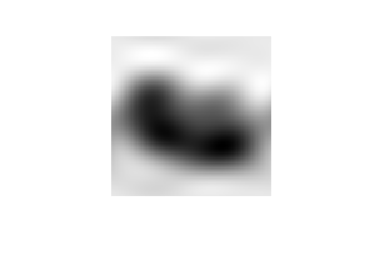


    [testcar71DFT, phase] = AmpPhaseDFT(mycars(:,:,71));
    testcar71DFT(:, 4:126) = zeros([65 123]);
    testcar71DFT(5:65, :) = zeros([61 128]);
    testcar71IDFT = ReconfromAmpPhase(testcar71DFT, phase);
    imshow(testcar71IDFT, [])

    errtest(3) = error(testcar71IDFT, mycars(:,:,71))

error = 0.1713

errtest =     0.1986    0.1849    0.1713    0.1849


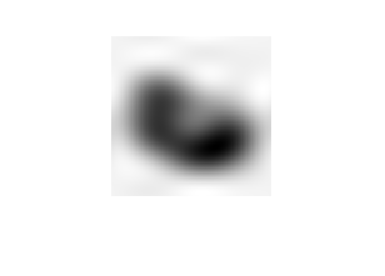


    [testcar72DFT, phase] = AmpPhaseDFT(mycars(:,:,72));
    testcar72DFT(:, 4:126) = zeros([65 123]);
    testcar72DFT(5:65, :) = zeros([61 128]);
    testcar72IDFT = ReconfromAmpPhase(testcar72DFT, phase);
    imshow(testcar72IDFT, [])

    errtest(4) = error(testcar72IDFT, mycars(:,:,72))

error = 0.2049

errtest =     0.1986    0.1849    0.1713    0.2049


    
    err4

err4 =     0.1843    0.1960    0.1777    0.1849


    
    errtest = errtest';

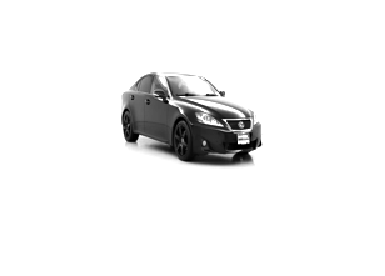


    mycars_testing = mycars(:,:,65:80);
    A2 = zeros([16 16384]);
    
    for j = 1:16
        tmp = reshape(mycars_testing(:,:,j),1,[]);
        A2(j,:) = tmp;
    end

    meanImg = mean(A2);
    
    morph_index1 = 69-64;
    morph_index2 = 72-64;
    
    imshow(mycars_testing(:,:,morph_index1));

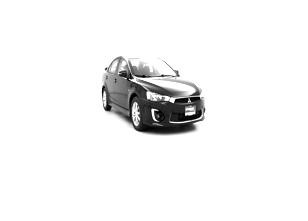

    testcar1 = reshape(mycars_testing(:,:,morph_index1),[],1);
    coeffs1 = eigencars*(testcar1-meanImg');
    reconstructed1 = (eigencars'*coeffs1)'+meanImg;

    imshow(mycars_testing(:,:,morph_index2));

    testcar2 = reshape(mycars_testing(:,:,morph_index2),[],1);
    coeffs2 = eigencars*(testcar2-meanImg');
    reconstructed2 = (eigencars'*coeffs2)'+meanImg;
    imshow(reconstructed2)

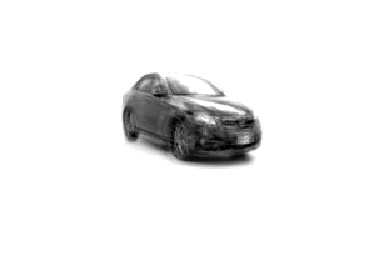


    morphs = zeros([11 16384]);
    for i = 1:11
        coeffs = coeffs1 + (coeffs2 - coeffs1)*(i-1)*.1;
        morphs(i,:) = ((eigencars')*coeffs)'+meanImg;
    end
    
    t_morph = morphs(6,:);

    imshow(reshape(morphs(1,:), 128, 128))

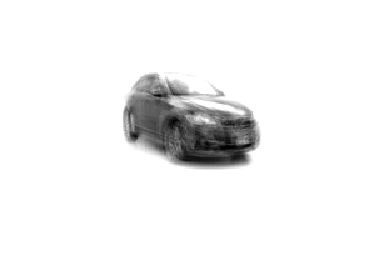

    imshow(reshape(t_morph, 128, 128))

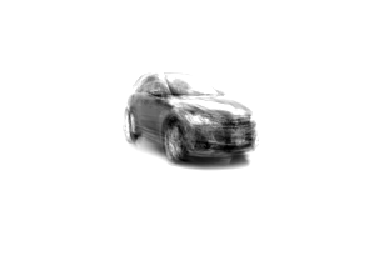

    imshow(reshape(morphs(11,:), 128, 128))


    t_morph = reshape(t_morph, 128, 128);




function error = error(genIm, baseIm)
    errorIm = genIm - baseIm;
    error = (mean(errorIm.^2, 'all'))^.5
end